# 1.1

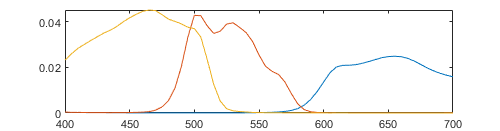

n = length(Ad);
x = linspace(400,700,n);
plot(x,Ad)

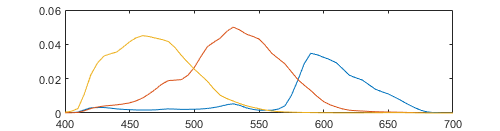

plot(x,Ad2)

Ad & Ad2 looks similar but not exact. They will definitly give different outputs. We think Ad2 will give a higher contrast image.

Answer: No.

# 1.2

## Camera 1

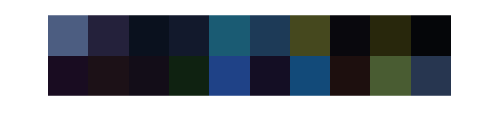

e = CIED65 .* chips20;

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad'*e';

showRGB(d')

## Camera 2

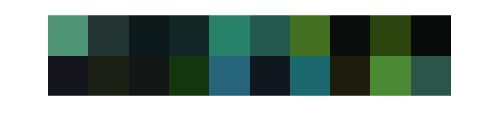

% raw (i.e. un-calibrated) camera output for the 20 surfaces
d = Ad2'*e';

showRGB(d')

# 2.1

ref1 = Ad'*CIED65';
ref2 = Ad2'*CIED65';

cf1 = ones(3,1) ./ ref1

cf1 =     2.4579
    1.6735
    1.0250


cf2 = ones(3,1) ./ ref2

cf2 =     2.2382
    1.0786
    1.1449


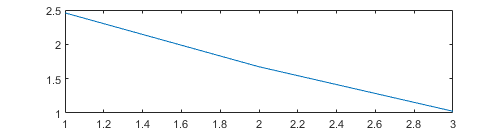


plot(cf1)

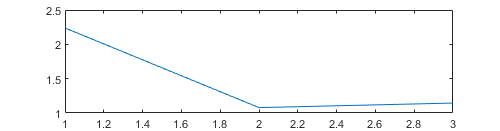

plot(cf2)

# 2.2

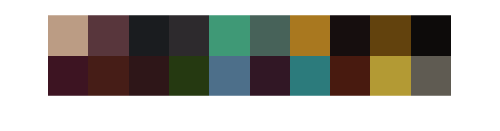

e = CIED65 .* chips20;

RAW_C1_CIED65 = Ad'*e';
RAW_C2_CIED65 = Ad2'*e';

CAL_DATA_C1_CIED65 = RAW_C1_CIED65 .* cf1;
CAL_DATA_C2_CIED65 = RAW_C2_CIED65 .* cf2;
 
showRGB(CAL_DATA_C1_CIED65')

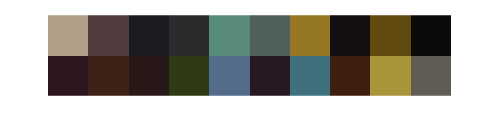

showRGB(CAL_DATA_C2_CIED65')

# 2.3

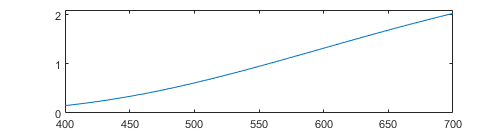

n = length(CIEA);
x = linspace(400,700,n);
plot(x,CIEA)
ylim([0,2.1])

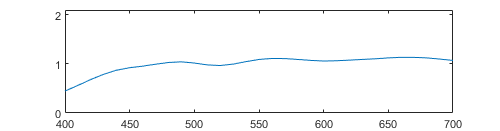

plot(x,CIEB)
ylim([0,2.1])

# 2.4

e = CIED65 .* chips20;
e2 = CIEA .* chips20;

% 1 Taking a picture of 20 surfaces
d1_raw_65 = Ad'*e';
d1_raw_CIEA = Ad'*e2';

% 2 Taking a picture of a completely white surface (ones)
d1_raw_65_v = Ad'*CIED65';
d1_raw_CIEA_v = Ad'*CIEA';

% 3 Calibration factors, same!
cf1 = ones(3,1) ./ d1_raw_65_v;
cf2 = ones(3,1) ./ d1_raw_CIEA_v;

% 1 multiplied with calibration factors
RGB_cal_CIE65 = d1_raw_65 .* cf1;
RGB_cal_CIEA = d1_raw_CIEA .* cf2;

showRGB(d1_raw_65')

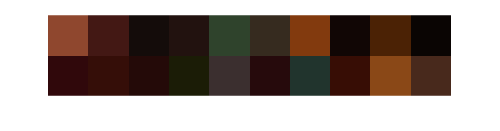

showRGB(d1_raw_CIEA')


showRGB(RGB_cal_CIE65')

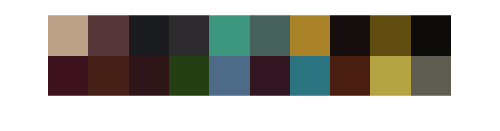

showRGB(RGB_cal_CIEA')

# 2.5

% d = Ad' * (chips20 .* CIEA)'
e = CIED65 .* chips20;
e2 = CIEA .* chips20;

% 1 Taking a picture of 20 surfaces
d1_raw_65 = Ad'*e';
d1_raw_CIEA = Ad'*e2';

ref1 = Ad'*CIED65';
ref2 = Ad'*CIEA';

cf = ones(3,1) ./ ref1;
cf2 = ones(3,1) ./ ref2;

RGB_cal_D65 = d1_raw_65 .* cf;
RGB_cal_A = d1_raw_CIEA .* cf2;

showRGB(RGB_cal_D65')

showRGB(RGB_cal_A')

# 3.1

% d = Ad' * (chips20 .* CIEA)'
% Facit
k = 100 ./ (CIED65 * xyz(:,2))

k = 4.6460


xyzValuesFromSpectra = xyz'*( CIED65 .* chips20 )' * k

xyzValuesFromSpectra =    66.5076   29.1415   10.3354   17.0944   37.2524   31.4696   51.8681    7.1516   35.7168    4.5704   14.7977   21.2515   13.6952   19.1563   34.5574   13.8335   26.8255   20.8937   59.1042   36.1553
   67.2653   25.9561   10.4588   16.8158   49.3000   35.3276   57.1830    6.4429   38.2742    4.5382   10.4425   18.0936   11.4180   25.1057   36.1143   10.5687   34.9493   17.7770   67.6801   37.2942
   61.0087   28.3929   14.4753   20.9340   50.2915   40.5003   10.0020    6.4265    5.4609    4.4085   16.5167   10.6582   11.4388    7.5209   65.7332   18.0017   54.8397    6.5922   17.7720   37.8082


# 3.2

CAL_DATA_C1_CIED65_XYZ = M_XYZ2RGB \ CAL_DATA_C1_CIED65

CAL_DATA_C1_CIED65_XYZ =    61.4216   26.0837   10.2211   16.2227   39.8786   31.5440   46.4218    6.3725   25.9743    4.1970   15.0404   16.9131   12.2893   15.0703   37.7502   13.7985   33.1094   16.3093   54.2934   33.8779
   63.0462   24.2983   10.8037   16.6752   51.3648   35.8823   48.7659    5.9971   27.0307    4.2841   11.6314   14.4964   10.7275   19.4173   41.3933   11.5790   41.7006   13.6408   59.6931   35.7370
   57.9539   25.7464   13.0108   18.9900   51.3964   38.3589   18.3944    5.9291    8.5139    4.1745   13.9536   10.4942   10.4511    9.3090   57.3145   15.1818   52.1366    7.2105   27.8020   35.4879


C_XYZ = CAL_DATA_C1_CIED65_XYZ

C_XYZ =    61.4216   26.0837   10.2211   16.2227   39.8786   31.5440   46.4218    6.3725   25.9743    4.1970   15.0404   16.9131   12.2893   15.0703   37.7502   13.7985   33.1094   16.3093   54.2934   33.8779
   63.0462   24.2983   10.8037   16.6752   51.3648   35.8823   48.7659    5.9971   27.0307    4.2841   11.6314   14.4964   10.7275   19.4173   41.3933   11.5790   41.7006   13.6408   59.6931   35.7370
   57.9539   25.7464   13.0108   18.9900   51.3964   38.3589   18.3944    5.9291    8.5139    4.1745   13.9536   10.4942   10.4511    9.3090   57.3145   15.1818   52.1366    7.2105   27.8020   35.4879


REF_XYZ = xyzValuesFromSpectra

REF_XYZ =    66.5076   29.1415   10.3354   17.0944   37.2524   31.4696   51.8681    7.1516   35.7168    4.5704   14.7977   21.2515   13.6952   19.1563   34.5574   13.8335   26.8255   20.8937   59.1042   36.1553
   67.2653   25.9561   10.4588   16.8158   49.3000   35.3276   57.1830    6.4429   38.2742    4.5382   10.4425   18.0936   11.4180   25.1057   36.1143   10.5687   34.9493   17.7770   67.6801   37.2942
   61.0087   28.3929   14.4753   20.9340   50.2915   40.5003   10.0020    6.4265    5.4609    4.4085   16.5167   10.6582   11.4388    7.5209   65.7332   18.0017   54.8397    6.5922   17.7720   37.8082



[L, a, b] =  xyz2lab(C_XYZ(1,:)', C_XYZ(2,:)', C_XYZ(3,:)')

L =    83.4667
   56.3853
   39.2478
   47.8482
   76.8995
   66.4299
   75.3054
   29.4051
   59.0028
   24.5893


a =    -0.7592
    9.6834
   -2.7344
   -0.6159
  -29.8395
  -12.5715
   -3.7177
    5.3907
   -2.0492
    0.0137


b =    13.6609
    4.3697
   -0.6718
    1.2703
    8.5309
    4.5707
   49.7601
    4.4657
   46.0338
    4.3107



C_LAB = zeros(3,20)

C_LAB =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


C_LAB(1,:) = L

C_LAB =    83.4667   56.3853   39.2478   47.8482   76.8995   66.4299   75.3054   29.4051   59.0028   24.5893   40.6243   44.9366   39.1176   51.1719   70.4506   40.5391   70.6640   43.7133   81.6711   66.3184
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


C_LAB(2,:) = a

C_LAB =    83.4667   56.3853   39.2478   47.8482   76.8995   66.4299   75.3054   29.4051   59.0028   24.5893   40.6243   44.9366   39.1176   51.1719   70.4506   40.5391   70.6640   43.7133   81.6711   66.3184
   -0.7592    9.6834   -2.7344   -0.6159  -29.8395  -12.5715   -3.7177    5.3907   -2.0492    0.0137   23.6820   15.7752   12.7397  -21.6047   -8.7569   16.4670  -25.2440   17.6945  -10.2610   -3.8389
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


C_LAB(3,:) = b

C_LAB =    83.4667   56.3853   39.2478   47.8482   76.8995   66.4299   75.3054   29.4051   59.0028   24.5893   40.6243   44.9366   39.1176   51.1719   70.4506   40.5391   70.6640   43.7133   81.6711   66.3184
   -0.7592    9.6834   -2.7344   -0.6159  -29.8395  -12.5715   -3.7177    5.3907   -2.0492    0.0137   23.6820   15.7752   12.7397  -21.6047   -8.7569   16.4670  -25.2440   17.6945  -10.2610   -3.8389
   13.6609    4.3697   -0.6718    1.2703    8.5309    4.5707   49.7601    4.4657   46.0338    4.3107   -0.5618   15.7693    5.8591   30.0166   -8.1980   -3.5089   -2.9445   24.1601   44.8426    7.8996



[L, a, b] =  xyz2lab(REF_XYZ(1,:)', REF_XYZ(2,:)', REF_XYZ(3,:)')

L =    85.6378
   57.9954
   38.6537
   48.0271
   75.6376
   66.0029
   80.2824
   30.5033
   68.2222
   25.3763


a =     1.3836
   14.8521
    0.7011
    3.4454
  -32.7209
  -11.0011
  -10.4846
    8.5388
   -5.8057
    1.6639


b =    14.6783
    3.1531
   -5.1682
   -2.0142
    7.4497
    1.3212
   78.1287
    4.3503
   73.3885
    4.4627



REF_LAB = zeros(3,20)

REF_LAB =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


REF_LAB(1,:) = L

REF_LAB =    85.6378   57.9954   38.6537   48.0271   75.6376   66.0029   80.2824   30.5033   68.2222   25.3763   38.6252   49.6095   40.2758   57.1783   66.6072   38.8443   65.7092   49.2245   85.8462   67.4972
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


REF_LAB(2,:) = a

REF_LAB =    85.6378   57.9954   38.6537   48.0271   75.6376   66.0029   80.2824   30.5033   68.2222   25.3763   38.6252   49.6095   40.2758   57.1783   66.6072   38.8443   65.7092   49.2245   85.8462   67.4972
    1.3836   14.8521    0.7011    3.4454  -32.7209  -11.0011  -10.4846    8.5388   -5.8057    1.6639   30.8508   17.6534   16.9504  -25.1884   -2.7520   23.9919  -27.4848   17.6167  -16.4674   -1.2246
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


REF_LAB(3,:) = b

REF_LAB =    85.6378   57.9954   38.6537   48.0271   75.6376   66.0029   80.2824   30.5033   68.2222   25.3763   38.6252   49.6095   40.2758   57.1783   66.6072   38.8443   65.7092   49.2245   85.8462   67.4972
    1.3836   14.8521    0.7011    3.4454  -32.7209  -11.0011  -10.4846    8.5388   -5.8057    1.6639   30.8508   17.6534   16.9504  -25.1884   -2.7520   23.9919  -27.4848   17.6167  -16.4674   -1.2246
   14.6783    3.1531   -5.1682   -2.0142    7.4497    1.3212   78.1287    4.3503   73.3885    4.4627   -9.6861   23.3634    5.1309   46.2606  -22.1750  -12.3321  -14.0762   35.9819   69.1621    7.0722



dE = euclidean_distance_lab(REF_LAB, C_LAB)

dE =     3.2156    5.5486    5.6898    5.2263    3.3262    3.6343   29.5862    3.3362   29.1100    1.8346   11.7746    9.1123    4.4273   17.6858   15.6904   11.7195   12.3890   13.0436   25.4438    2.9847



mean(dE)

ans = 10.7389

max(dE)

ans = 29.5862

# # Functions

function dE = euclidean_distance_lab(V1, V2)
    L1 = V1(1,:);
    L2 = V2(1,:);

    a1 = V1(2,:);
    a2 = V2(2,:);

    b1 = V1(3,:);
    b2 = V2(3,:);

    dE = sqrt((L1-L2).^2 + (a1-a2).^2 + (b1-b2).^2);
end